clearvars
format long

# Research Techniques Project

## Milestone 1 (6 October)

## Data Exploration of BD+55_441

For this milestone, BD+55_441 is displayed and explored in detail. The other sources are briefly imported in upcoming sections.

opts = detectImportOptions("BD+55_441.txt");
opts.DataLines = 3;
opts.VariableNames = {'B_time','B_flux','R_time','R_flux','V_time','V_flux'};

"time" is in the units of days and "flux" is "rel_flux_T1" from AstroImageJ outputs. 

opts.VariableTypes = {'double','double','double','double','double','double'};
preview("BD+55_441.txt",opts)

ans = 8×6 table
      B_time        B_flux       R_time        R_flux       V_time        V_flux 
    ___________    ________    ___________    ________    ___________    ________

     58732.6843    3.497996    58732.68459     1.96183    58732.68445    2.352058
     58732.6843    3.497996    58732.68504    1.942857     58732.6849    2.360458
    58732.68475    3.487289    58732.68549    1.947021    58732.68535    2.329957
     58732.6852    3.450942    58732.68594    1.930594     58732.6858    2.344889
    58732.68565    3.497567    58732.68639    1.942537    58732.68625    2.361048
     58732.6861    3.461555    58732.68684    1.935141    58732.68669    2.333341
    58732.68655    3.431248    58732.68729     1.93129    58732.68714    2.331904
      58732.687    3.455091    58732.6877

BD55_441 = readmatrix("BD+55_441.txt",opts);
whos BD55_441

  Name            Size            Bytes  Class     Attributes

  BD55_441      101x6              4848  double              



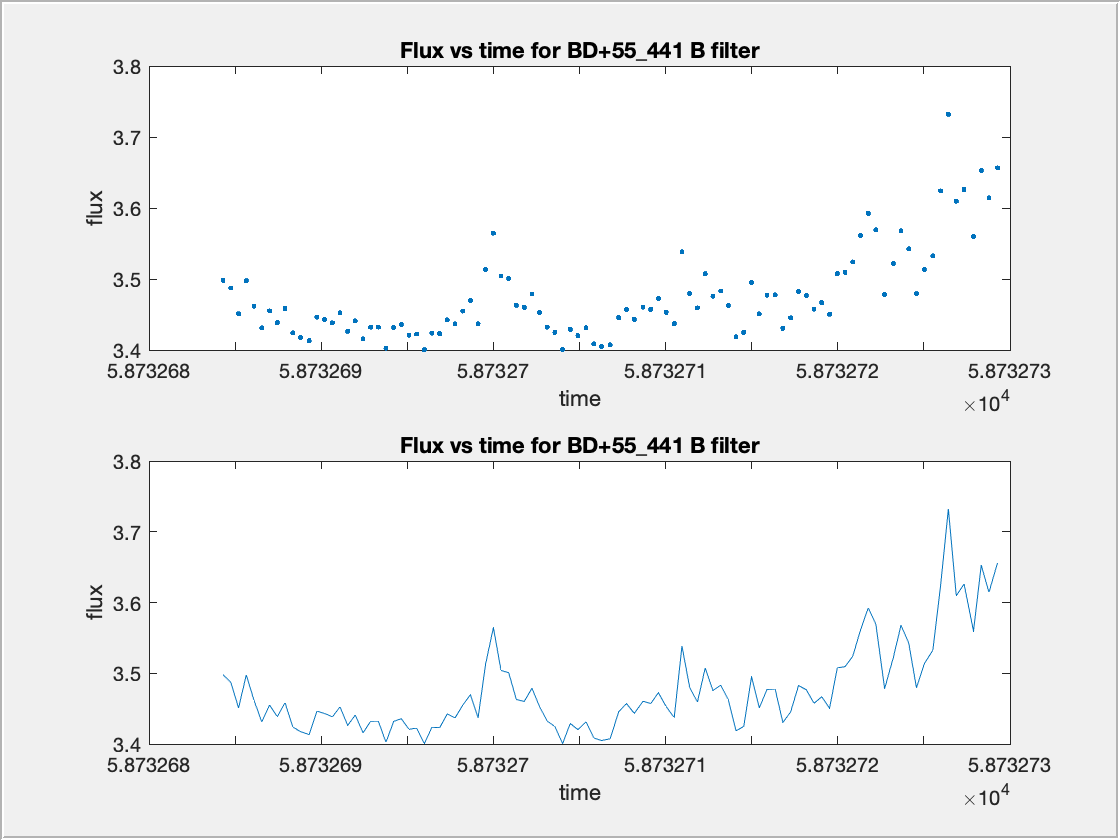

hf_sub(1) = figure(1);
hp(1) = uipanel('Parent',hf_sub(1),'Position',[0 0 1 1]);
subplot(2,1,1,'Parent',hp(1));
plot(BD55_441(:,1),BD55_441(:,2),'.')
title('Flux vs time for BD+55\_441 B filter');
xlabel('time'),ylabel('flux');
subplot(2,1,2,'Parent',hp(1));
plot(BD55_441(:,1),BD55_441(:,2)),title('Flux vs time for BD+55\_441 B filter')
xlabel('time');
ylabel('flux');

Noting the graph above - displayed in discrete points and as a line graph - there is some periodicity. There are peaks at 58732.70, 58732.711 and 58732.722.

r = abs([0; BD55_441(:,1)] - [BD55_441(:,1);0]);
round(mean(r(3:end-1)),8) %average period between measurements

ans =      4.543400000000000e-04


round(std(r(3:end-1)),8) %standard deviation - as a measurement of variation in period

ans =      1.885000000000000e-05


## Periodicity between filters

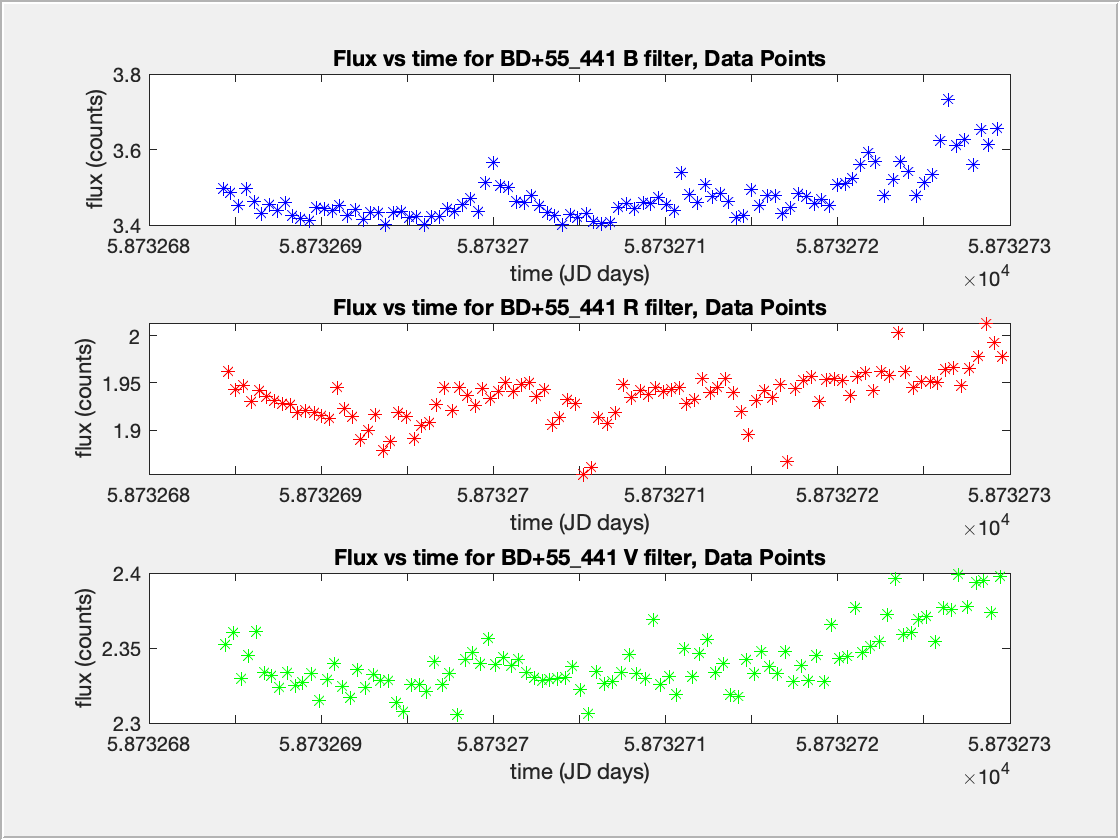

hf_sub(2) = figure(2);
hp(2) = uipanel('Parent',hf_sub(2),'Position',[0 0 1 1]);
subplot(3,1,1,'Parent',hp(2));
% plotting in blue because B filter is blue light (~400-500 nm)
plot(BD55_441(:,1),BD55_441(:,2),'*b')
title('Flux vs time for BD+55\_441 B filter, Data Points');
xlabel('time (JD days)');
ylabel('flux (counts)');
subplot(3,1,2,'Parent',hp(2));
% plotting in red because R filter is red light (~550-800 nm)
plot(BD55_441(:,3),BD55_441(:,4),'*r');
title('Flux vs time for BD+55\_441 R filter, Data Points');
xlabel('time (JD days)');
ylabel('flux (counts)');
subplot(3,1,3,'Parent',hp(2));
% plotting green but V filter is visible light (~500-700 nm)
plot(BD55_441(:,5),BD55_441(:,6),'*g');
title('Flux vs time for BD+55\_441 V filter, Data Points');
xlabel('time (JD days)');
ylabel('flux (counts)');

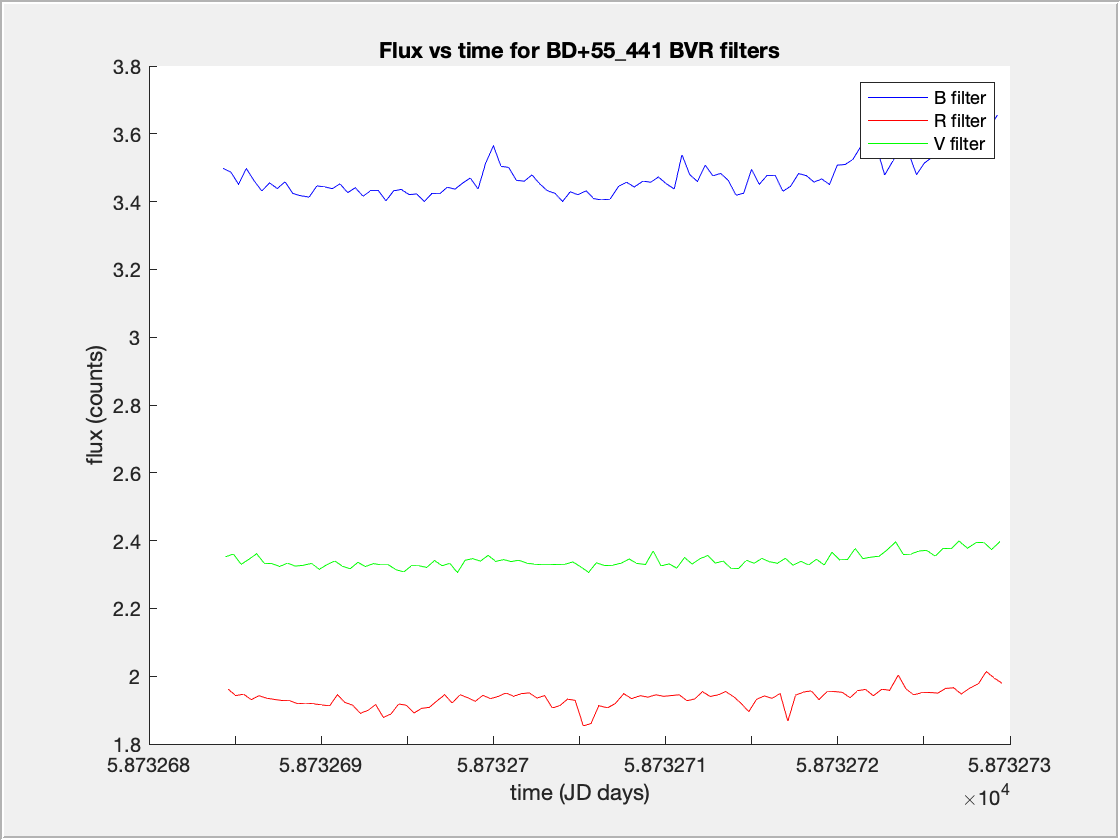


hf_sub(3) = figure(3);
hp(3) = uipanel('Parent',hf_sub(3),'Position',[0 0 1 1]);
subplot(1,1,1,'Parent',hp(3))
hold on
plot(BD55_441(:,1),BD55_441(:,2), 'b')
plot(BD55_441(:,3),BD55_441(:,4), 'r')
plot(BD55_441(:,5),BD55_441(:,6), 'g')
hold off
title('Flux vs time for BD+55\_441 BVR filters');
xlabel('time (JD days)');
legend('B filter', 'R filter', 'V filter');
ylabel('flux (counts)');

## Interpolation investigation

custom linear

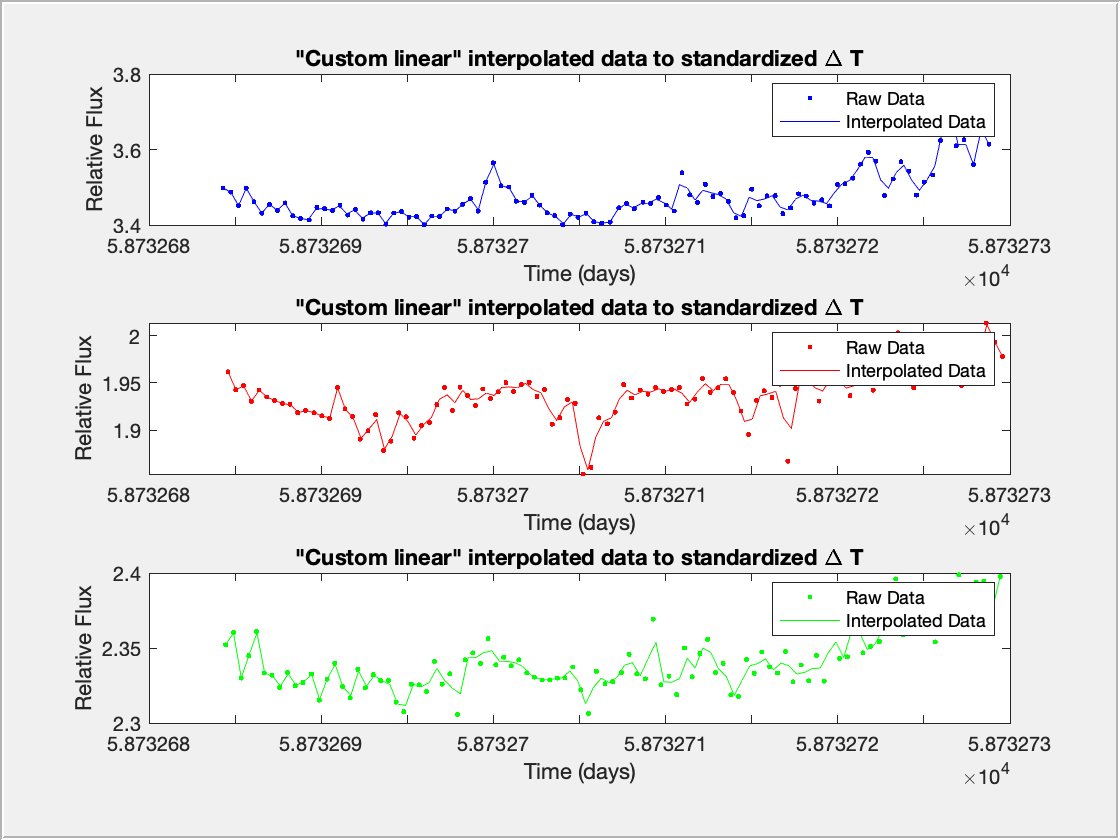

hf_sub(4) = figure(4);
hp(4) = uipanel('Parent',hf_sub(4),'Position',[0 0 1 1]);
subplot(3,1,1,'Parent',hp(4));
[Tnew,Mnew] = Interp_Lin(BD55_441(1:100,1),BD55_441(1:100,2));
plot(BD55_441(1:100,1),BD55_441(1:100,2),'.b',Tnew,Mnew,'b');
title('"Custom linear" interpolated data to standardized \Delta T');
legend('Raw Data','Interpolated Data');
xlabel('Time (days)');
ylabel('Relative Flux');
subplot(3,1,2,'Parent',hp(4));
[Tnew,Mnew] = Interp_Lin(BD55_441(1:100,3),BD55_441(1:100,4));
plot(BD55_441(1:100,3),BD55_441(1:100,4),'.r',Tnew,Mnew,'r');
title('"Custom linear" interpolated data to standardized \Delta T');
legend('Raw Data','Interpolated Data');
xlabel('Time (days)');
ylabel('Relative Flux');
subplot(3,1,3,'Parent',hp(4));
[Tnew,Mnew] = Interp_Lin(BD55_441(1:100,5),BD55_441(1:100,6));
plot(BD55_441(1:100,5),BD55_441(1:100,6),'.g',Tnew,Mnew,'g');
title('"Custom linear" interpolated data to standardized \Delta T');
legend('Raw Data','Interpolated Data');
xlabel('Time (days)');
ylabel('Relative Flux');

Nearest

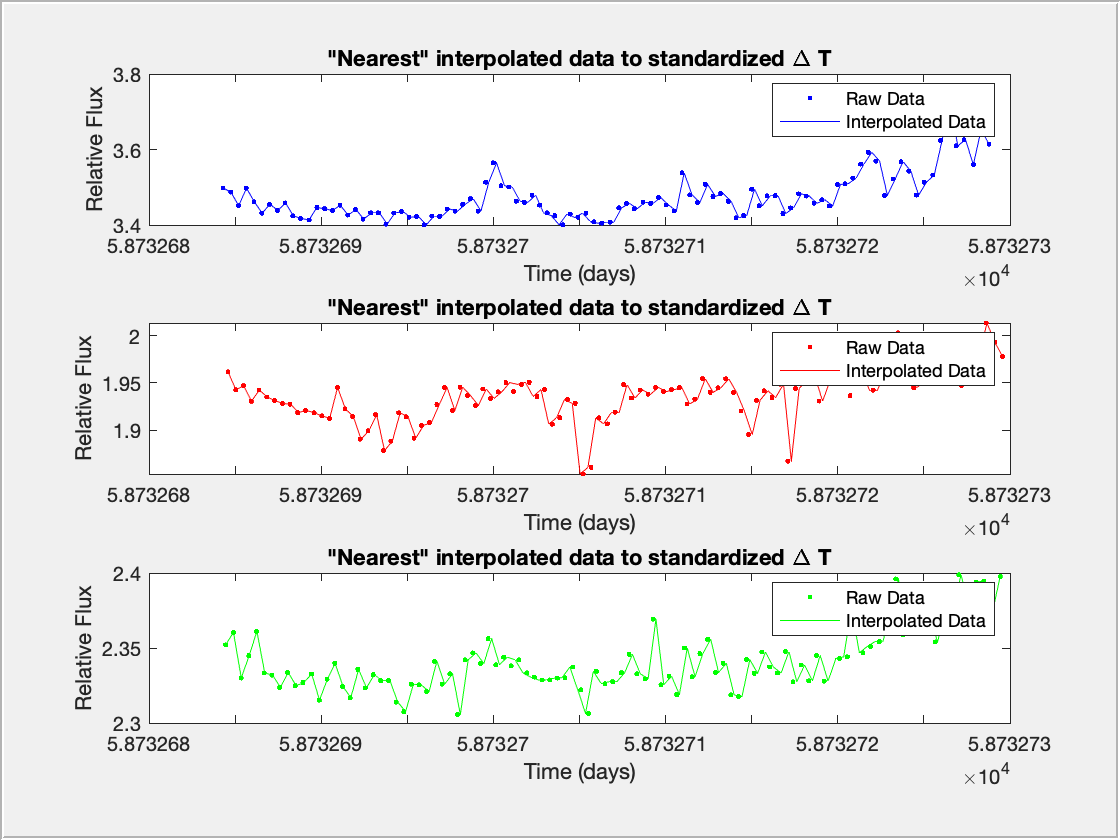

hf_sub(5) = figure(5);
hp(5) = uipanel('Parent',hf_sub(5),'Position',[0 0 1 1]);
subplot(3,1,1,'Parent',hp(5));
[Tnew,Mnew] = Interp_nearest(BD55_441(2:100,1),BD55_441(2:100,2));
plot(BD55_441(1:100,1),BD55_441(1:100,2),'.b',Tnew,Mnew,'b');
title('"Nearest" interpolated data to standardized \Delta T');
legend('Raw Data','Interpolated Data');
xlabel('Time (days)');
ylabel('Relative Flux');
subplot(3,1,2,'Parent',hp(5));
[Tnew,Mnew] = Interp_nearest(BD55_441(1:100,3),BD55_441(1:100,4));
plot(BD55_441(1:100,3),BD55_441(1:100,4),'.r',Tnew,Mnew,'r');
title('"Nearest" interpolated data to standardized \Delta T');
legend('Raw Data','Interpolated Data');
xlabel('Time (days)');
ylabel('Relative Flux');
subplot(3,1,3,'Parent',hp(5));
[Tnew,Mnew] = Interp_nearest(BD55_441(1:100,5),BD55_441(1:100,6));
plot(BD55_441(1:100,5),BD55_441(1:100,6),'.g',Tnew,Mnew,'g');
title('"Nearest" interpolated data to standardized \Delta T');
legend('Raw Data','Interpolated Data');
xlabel('Time (days)');
ylabel('Relative Flux');

linear

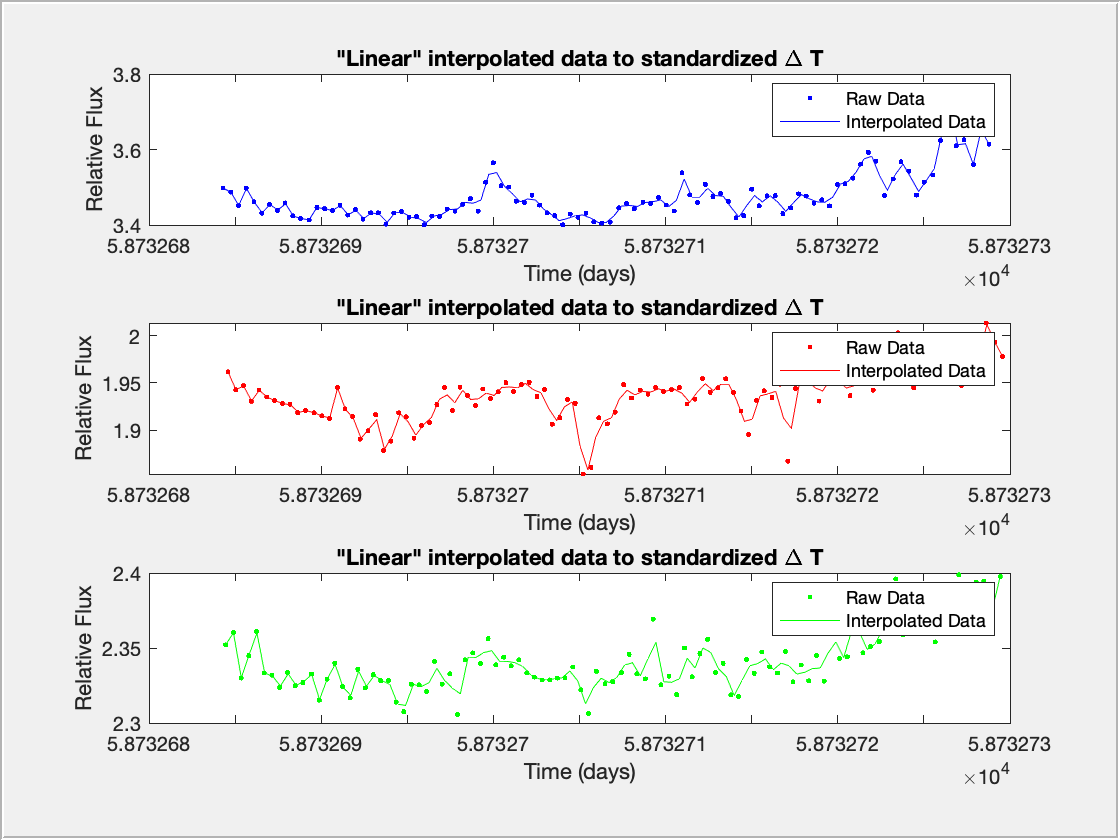

hf_sub(6) = figure(6);
hp(6) = uipanel('Parent',hf_sub(6),'Position',[0 0 1 1]);
subplot(3,1,1,'Parent',hp(6));
[Tnew,Mnew] = Interp_linear(BD55_441(2:100,1),BD55_441(2:100,2));
plot(BD55_441(1:100,1),BD55_441(1:100,2),'.b',Tnew,Mnew,'b');
title('"Linear" interpolated data to standardized \Delta T');
legend('Raw Data','Interpolated Data');
xlabel('Time (days)');
ylabel('Relative Flux');
subplot(3,1,2,'Parent',hp(6));
[Tnew,Mnew] = Interp_linear(BD55_441(1:100,3),BD55_441(1:100,4));
plot(BD55_441(1:100,3),BD55_441(1:100,4),'.r',Tnew,Mnew,'r');
title('"Linear" interpolated data to standardized \Delta T');
legend('Raw Data','Interpolated Data');
xlabel('Time (days)');
ylabel('Relative Flux');
subplot(3,1,3,'Parent',hp(6));
[Tnew,Mnew] = Interp_linear(BD55_441(1:100,5),BD55_441(1:100,6));
plot(BD55_441(1:100,5),BD55_441(1:100,6),'.g',Tnew,Mnew,'g');
title('"Linear" interpolated data to standardized \Delta T');
legend('Raw Data','Interpolated Data');
xlabel('Time (days)');
ylabel('Relative Flux');

spline

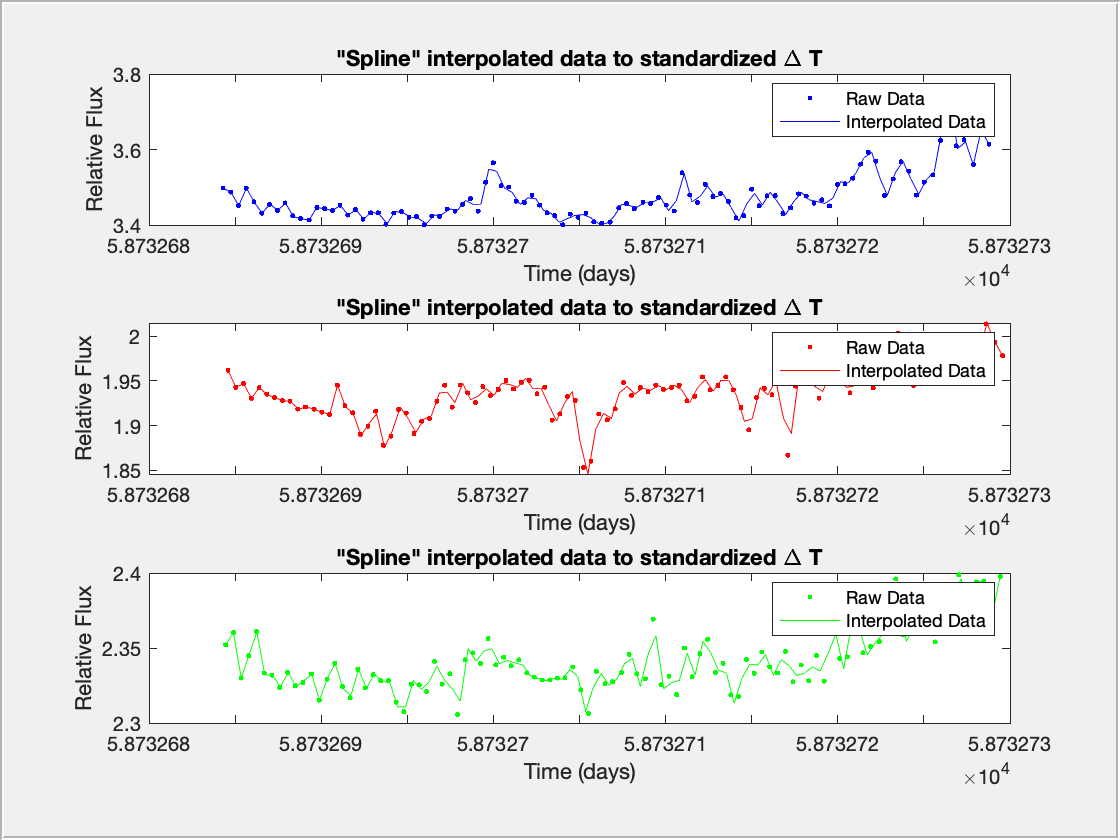

hf_sub(7) = figure(7);
hp(7) = uipanel('Parent',hf_sub(7),'Position',[0 0 1 1]);
subplot(3,1,1,'Parent',hp(7));
[Tnew,Mnew] = Interp_spline(BD55_441(2:100,1),BD55_441(2:100,2));
plot(BD55_441(1:100,1),BD55_441(1:100,2),'.b',Tnew,Mnew,'b');
title('"Spline" interpolated data to standardized \Delta T');
legend('Raw Data','Interpolated Data');
xlabel('Time (days)');
ylabel('Relative Flux');
subplot(3,1,2,'Parent',hp(7));
[Tnew,Mnew] = Interp_spline(BD55_441(1:100,3),BD55_441(1:100,4));
plot(BD55_441(1:100,3),BD55_441(1:100,4),'.r',Tnew,Mnew,'r');
title('"Spline" interpolated data to standardized \Delta T');
legend('Raw Data','Interpolated Data');
xlabel('Time (days)');
ylabel('Relative Flux');
subplot(3,1,3,'Parent',hp(7));
[Tnew,Mnew] = Interp_spline(BD55_441(1:100,5),BD55_441(1:100,6));
plot(BD55_441(1:100,5),BD55_441(1:100,6),'.g',Tnew,Mnew,'g');
title('"Spline" interpolated data to standardized \Delta T');
legend('Raw Data','Interpolated Data');
xlabel('Time (days)');
ylabel('Relative Flux');

polyfit - needs to be conditioned appropriately.



hf_sub(8) = figure(8);
hp(8) = uipanel('Parent',hf_sub(8),'Position',[0 0 1 1]);
subplot(3,1,1,'Parent',hp(8));
[Tnew,Mnew] = Interp_polyfit(BD55_441(2:100,1),BD55_441(2:100,2));

plot(BD55_441(1:100,1),BD55_441(1:100,2),'.b',Tnew,Mnew,'b');
title('"Polyfit" interpolated data to standardized \Delta T');
legend('Raw Data','Interpolated Data');
xlabel('Time (days)');
ylabel('Relative Flux');
subplot(3,1,2,'Parent',hp(8));
[Tnew,Mnew] = Interp_polyfit(BD55_441(1:100,3),BD55_441(1:100,4));

plot(BD55_441(1:100,3),BD55_441(1:100,4),'.r',Tnew,Mnew,'r');
title('"Polyfit" interpolated data to standardized \Delta T');
legend('Raw Data','Interpolated Data');
xlabel('Time (days)');
ylabel('Relative Flux');
subplot(3,1,3,'Parent',hp(8));
[Tnew,Mnew] = Interp_polyfit(BD55_441(1:100,5),BD55_441(1:100,6));

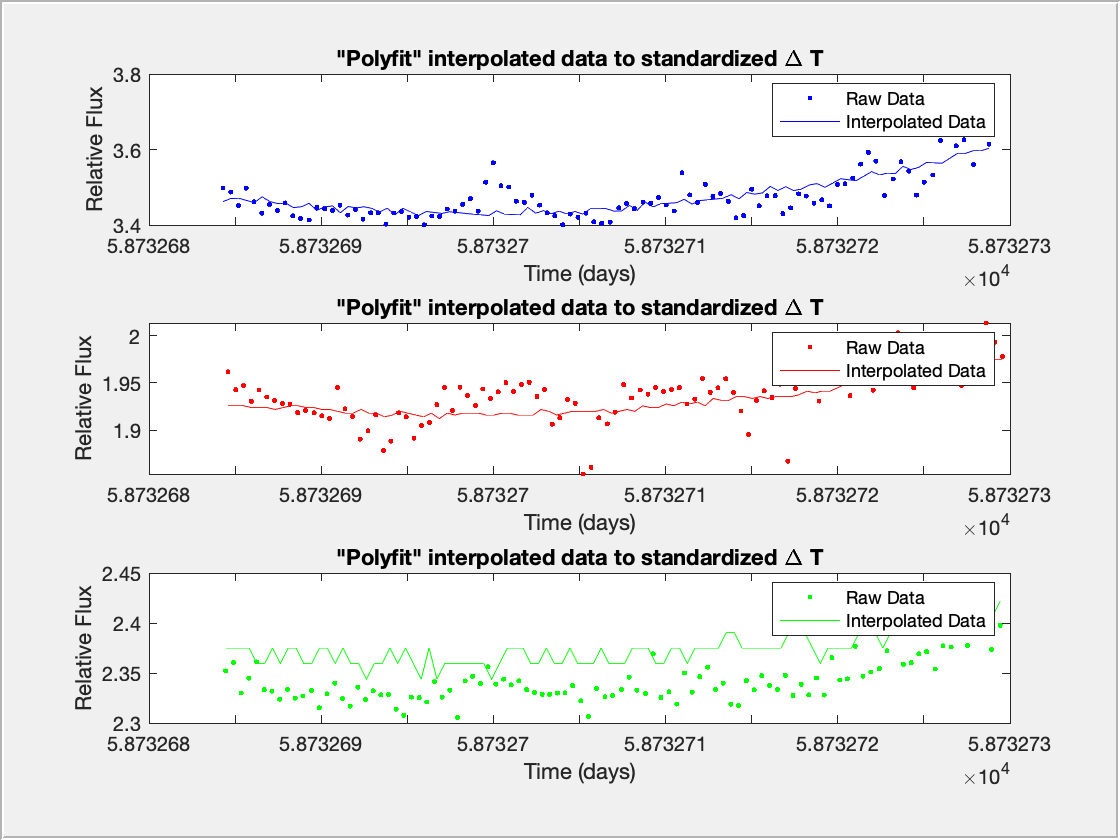

plot(BD55_441(1:100,5),BD55_441(1:100,6),'.g',Tnew,Mnew,'g');
title('"Polyfit" interpolated data to standardized \Delta T');
legend('Raw Data','Interpolated Data');
xlabel('Time (days)');
ylabel('Relative Flux');

## Input all data

**Text files:**

%BD+48_1098
opts = detectImportOptions("BD+48_1098.txt");
opts.DataLines = 3;
opts.VariableNames = {'B_time','B_flux','R_time','R_flux','V_time','V_flux'};
opts.VariableTypes = {'double','double','double','double','double','double'};
BD48_1098 = rmmissing(readmatrix("BD+55_441.txt",opts)); %the matrix data of the text file
%preview("BD+48_1098.txt",opts)
whos BD48_1098

  Name             Size            Bytes  Class     Attributes

  BD48_1098      100x6              4800  double              



%HD28497
opts = detectImportOptions("HD28497.txt");
opts.DataLines = 3;
opts.VariableNames = {'B_time','B_flux','R_time','R_flux','V_time','V_flux'};
opts.VariableTypes = {'double','double','double','double','double','double'};
HD28497 = rmmissing(readmatrix("HD28497.txt",opts)) %the matrix data of the text file

HD28497 = 	1.0e+04 *

   5.844163256000000   0.151884039400000   5.844163279000000   0.047485834000000   5.844163267000000   0.069815062400000
   5.844163294000000   0.157713255000000   5.844163317000000   0.047850097100000   5.844163304999999   0.065578599100000
   5.844163332000000   0.147648080800000   5.844163355000000   0.050717498800000   5.844163344000000   0.074395448000000
   5.844163370000000   0.154105058200000   5.844163393000001   0.048745268800000   5.844163382000001   0.071764534300000
   5.844163409000000   0.154416998300000   5.844163431999999   0.046480291500000   5.844163420000000   0.070814725000000
   5.844163447000000   0.154034530100000   5.844163470000000   0.052878906200000   5.844163458000000   0.077323090500000
   5.844163485000000   0.158524561400000   5.844163508000000   0.050080829500000   5.844163497000000   0.071339644400000
   5.844163523000000   0.159731365000000   5.844163546000000   0.053844298900000   5.844163535000000   0.072074042600000
   5.84416


%preview("HD28497.txt",opts)
whos HD28497

  Name           Size            Bytes  Class     Attributes

  HD28497      600x6             28800  double              



%HD46131
opts = detectImportOptions("HD46131.txt");
opts.DataLines = 3;
opts.VariableNames = {'B_time','B_flux','R_time','R_flux','V_time','V_flux'};
opts.VariableTypes = {'double','double','double','double','double','double'};
HD46131 = rmmissing(readmatrix("HD46131.txt",opts)); %the matrix data of the text file
%preview("HD46131.txt",opts)
whos HD46131

  Name           Size            Bytes  Class     Attributes

  HD46131      250x6             12000  double              



%HD88661
opts = detectImportOptions("HD88661.txt");
opts.DataLines = 3;
opts.VariableNames = {'B_time','B_flux','R_time','R_flux','V_time','V_flux'};
opts.VariableTypes = {'double','double','double','double','double','double'};
HD88661 = rmmissing(readmatrix("HD88661.txt",opts)); %the matrix data of the text file
%preview("HD88661.txt",opts)
whos HD88661

  Name          Size            Bytes  Class     Attributes

  HD88661      35x6              1680  double              



%HD105521
opts = detectImportOptions("HD105521.txt");
opts.DataLines = 3;
opts.VariableNames = {'B_time','B_flux','R_time','R_flux','V_time','V_flux'};
opts.VariableTypes = {'double','double','double','double','double','double'};
HD105521 = rmmissing(readmatrix("HD105521.txt",opts)); %the matrix data of the text file
%preview("HD105521.txt",opts)
whos HD105521

  Name            Size            Bytes  Class     Attributes

  HD105521      180x6              8640  double              



%HD105521
opts = detectImportOptions("HD105521.txt");
opts.DataLines = 3;
opts.VariableNames = {'B_time','B_flux','R_time','R_flux','V_time','V_flux'};
opts.VariableTypes = {'double','double','double','double','double','double'};
HD105521 = rmmissing(readmatrix("HD105521.txt",opts)); %the matrix data of the text file
%preview("HD105521.txt",opts)
whos HD105521

  Name            Size            Bytes  Class     Attributes

  HD105521      180x6              8640  double              



**CSV files**

%HD106306
%B_filter
opts = detectImportOptions('HD106306_B.csv');
opts.DataLines = [2 Inf];
All_fields_available = opts.VariableNames;
opts.SelectedVariableNames = {'J_D__2400000','rel_flux_T1'};
%preview("HD106306_B.csv",opts)
HD106306_B = readmatrix("HD106306_B.csv",opts);

%R_filter
opts = detectImportOptions('HD106306_R.csv');
opts.DataLines = [2 Inf];
All_fields_available = opts.VariableNames;
opts.SelectedVariableNames = {'J_D__2400000','rel_flux_T1'};
%preview("HD106306_R.csv",opts)
HD106306_R = readmatrix("HD106306_R.csv",opts);

%V_filter
opts = detectImportOptions('HD106306_V.csv');
opts.DataLines = [2 Inf];
All_fields_available = opts.VariableNames;
opts.SelectedVariableNames = {'J_D__2400000','rel_flux_T1'};
%preview("HD106306_V.csv",opts)
HD106306_V = readmatrix("HD106306_V.csv",opts);

HD106306 = rmmissing([HD106306_B HD106306_R HD106306_V]); %the matrix data of the text file
whos HD106306

  Name            Size            Bytes  Class     Attributes

  HD106306      100x6              4800  double              



%HD147302
%B_filter
opts = detectImportOptions('HD147302_B.csv');
opts.DataLines = [2 Inf];
All_fields_available = opts.VariableNames;
opts.SelectedVariableNames = {'J_D__2400000','rel_flux_T1'};
%preview("HD147302_B.csv",opts)
HD147302_B = readmatrix("HD147302_B.csv",opts);

%R_filter
opts = detectImportOptions('HD147302_R.csv');
opts.DataLines = [2 Inf];
All_fields_available = opts.VariableNames;
opts.SelectedVariableNames = {'J_D__2400000','rel_flux_T1'};
%preview("HD147302_R.csv",opts)
HD147302_R = readmatrix("HD147302_R.csv",opts);

%V_filter
opts = detectImportOptions('HD147302_V.csv');
opts.DataLines = [2 Inf];
All_fields_available = opts.VariableNames;
opts.SelectedVariableNames = {'J_D__2400000','rel_flux_T1'};
%preview("HD147302_V.csv",opts)
HD147302_V = readmatrix("HD147302_V.csv",opts);

HD147302 = rmmissing([HD147302_B HD147302_R HD147302_V]); %the matrix data of the text file
whos HD147302

  Name            Size            Bytes  Class     Attributes

  HD147302      100x6              4800  double              



HD152060 and HD209522 can't be described in the same form as the others. Will investigate

close all   %closes all previous figures from milestone 1 so that the plots in milestone 2 and 3 work correctly

## Milestone 2 (13 October)

[https://www.mathworks.com/help/matlab/ref/fft.html?searchHighlight=fft&s_tid=srchtitle](https://www.mathworks.com/help/matlab/ref/fft.html?searchHighlight=fft&s_tid=srchtitle)

This is the source for implementing Fourier Transform for a Noisy Signal from the MathWorks documentation

### Using fft for HD28497

This star had the most data which made it ideal for performing a fourier transform. We chose linear interpolation for the purposes of this experiment at random. This is a feature to be explored later.

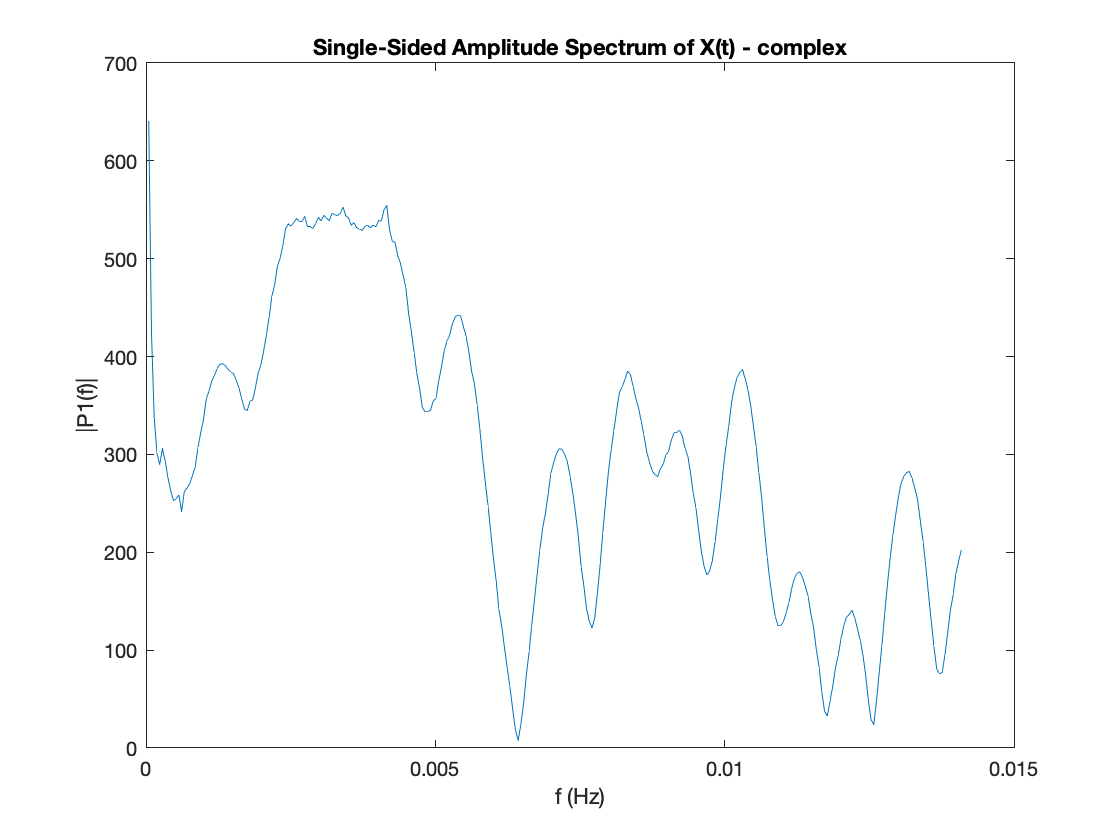

[Tnew,Mnew] = Interp_linear(HD28497(2:end,1),HD28497(2:end,2));
Tnew = Tnew*86400; %convert time from days to seconds
deltaT = Tnew(2)-Tnew(1);
Fs = 1/deltaT;           % Sampling frequency
T = deltaT;             % Sampling period
t = Tnew;                % Time vector
L = numel(Tnew);         % Length of signal
X = Mnew;               %signal with noise
%Fourier transformation
Y = fft(X);
P2complex = abs(Y/L); %real and imaginary parts together
P2real = real(Y);
P2imaginary = imag(Y);
P1complex = P2complex(1:floor(L/2)+1);
P1complex(2:end-1) = 2*P1complex(2:end-1);

%Plot

f = Fs*(0:(L/2))/L;
plot(f(2:end-1),P1complex(2:end-1))
title('Single-Sided Amplitude Spectrum of X(t) - complex')
xlabel('f (Hz)')
ylabel('|P1(f)|')

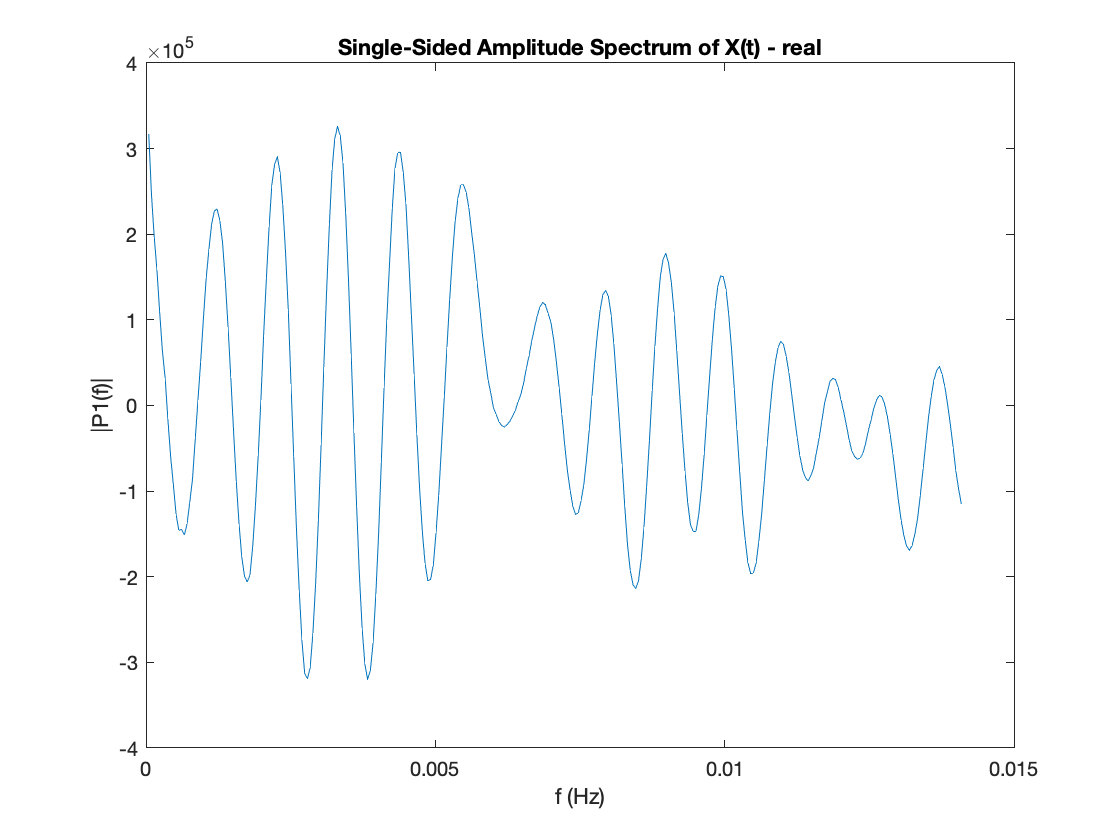

P1real = P2real(1:floor(L/2)+1);
P1real(2:end-1) = 2*P1real(2:end-1);
%plotting piece
f = Fs*(0:(L/2))/L;
plot(f(2:end-1),P1real(2:end-1))
title('Single-Sided Amplitude Spectrum of X(t) - real')
xlabel('f (Hz)')
ylabel('|P1(f)|')

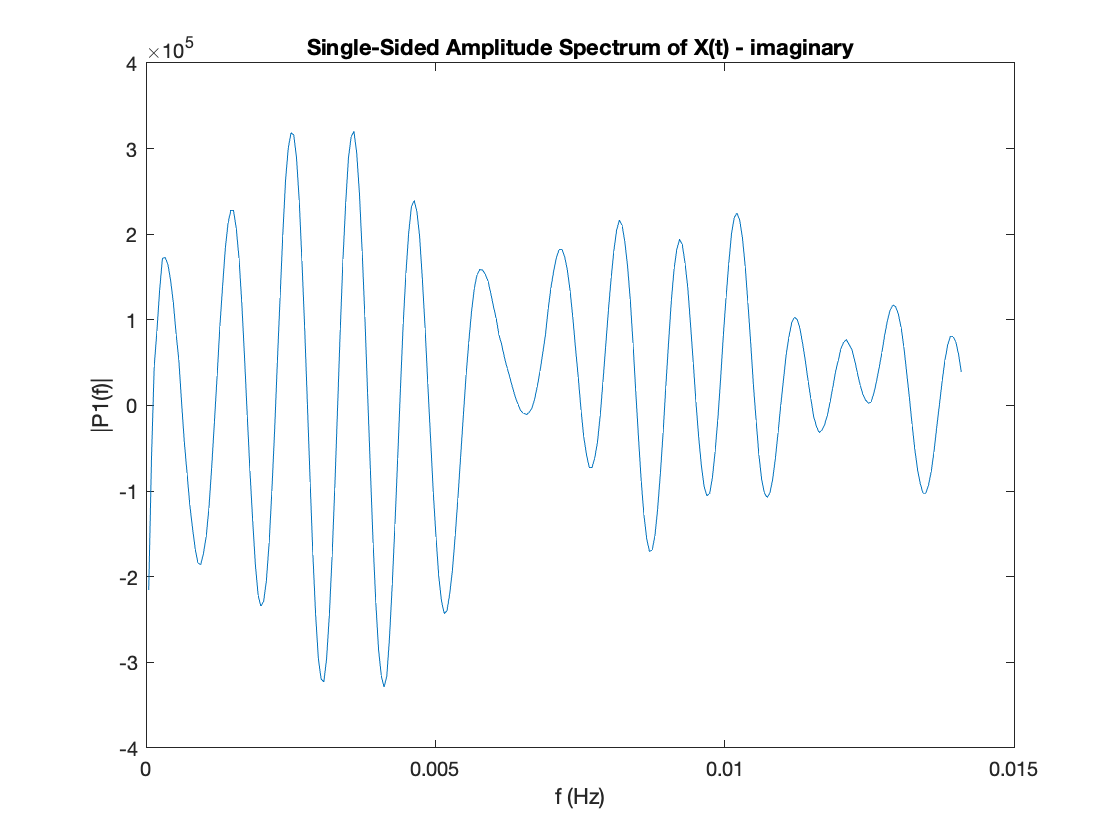

P1imaginary = P2imaginary(1:floor(L/2)+1);
P1imaginary(2:end-1) = 2*P1imaginary(2:end-1);
%plotting piece
f = Fs*(0:(L/2))/L;
plot(f(2:end-1),P1imaginary(2:end-1))
title('Single-Sided Amplitude Spectrum of X(t) - imaginary')
xlabel('f (Hz)')
ylabel('|P1(f)|')

### Using NUFFT - used the data without interpolation

Results for this one star using the complex combination was very similar to fft.

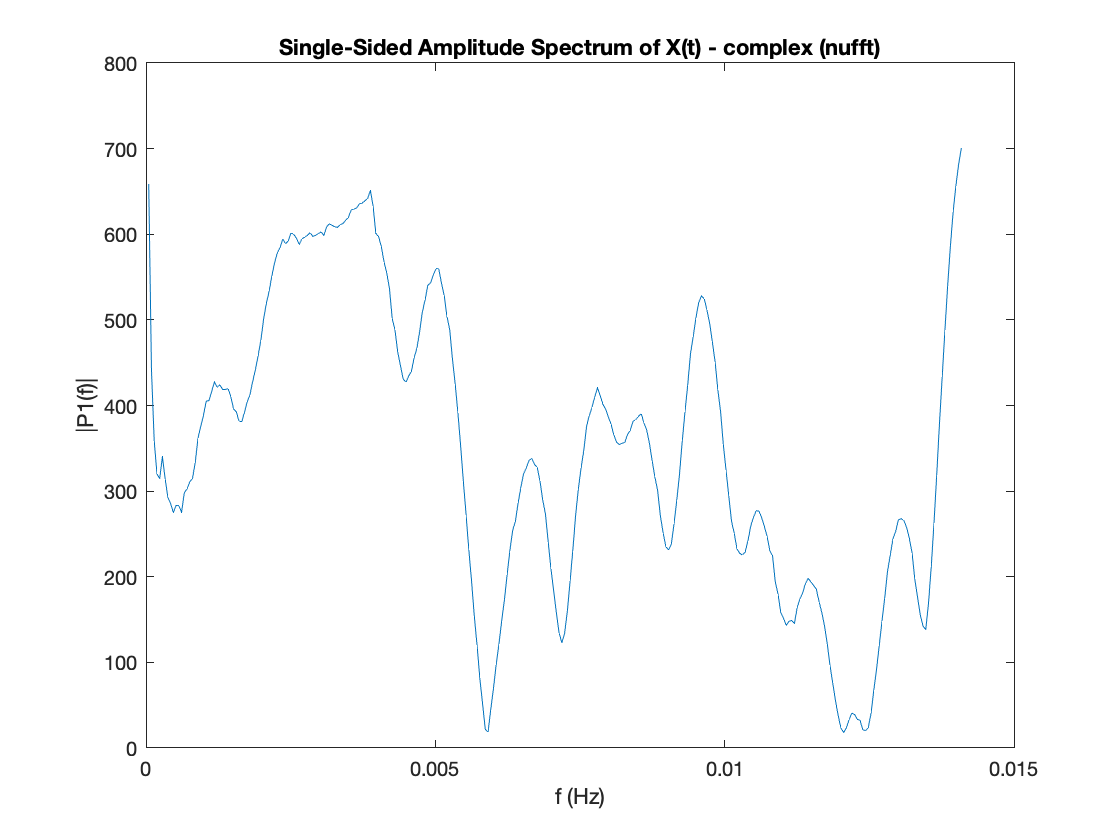

Tnew = HD28497(2:end,1);
Mnew = HD28497(2:end,2);
Tnew = Tnew*86400;
% --Find averaged time scale--
n = numel(Tnew);
sum = 0;
for l = 1:n-1
    sum = sum + abs(Tnew(l+1) - Tnew(l));
end
deltaT = sum / (n-1); %average time between points
Fs = 1/deltaT;           % Sampling frequency
T = deltaT;             % Sampling period
t = Tnew;                % Time vector
L = numel(Tnew);         % Length of signal
X = Mnew;               %signal with noise
%Fourier transformation
Y = nufft(X);
P2complex = abs(Y/L); %combination of real and imaginary
P2real = real(Y);
P2imaginary = imag(Y);
P1complex = P2complex(1:floor(L/2)+1);
P1complex(2:end-1) = 2*P1complex(2:end-1);
%plotting piece
f = Fs*(0:(L/2))/L;
plot(f(2:end-1),P1complex(2:end-1))
title('Single-Sided Amplitude Spectrum of X(t) - complex (nufft)')
xlabel('f (Hz)')
ylabel('|P1(f)|')

The investigation of the inverse fourier transform will be explored at a later date to complete milestone 2.

## Milestone 3 (including previously unfinished parts of milestone 2)

### Getting the Power Spectrum for HD28497

This star had the most data which made it ideal for performing a fourier transform. We chose linear interpolation for the purposes of this experiment at random. This is a feature to be explored late

Documentation:  We used a combination of the following sources to develop this:

- [https://www.mathworks.com/help/matlab/ref/fft.html?searchHighlight=fft&s_tid=srchtitle](https://www.mathworks.com/help/matlab/ref/fft.html?searchHighlight=fft&s_tid=srchtitle) (This is the source for implementing Fourier Transform for a Noisy Signal from the MathWorks documentation)

- Gilat, Example 7-6 (pg. 281)

- Gilat, Example 7-8 (pg 287)

r.

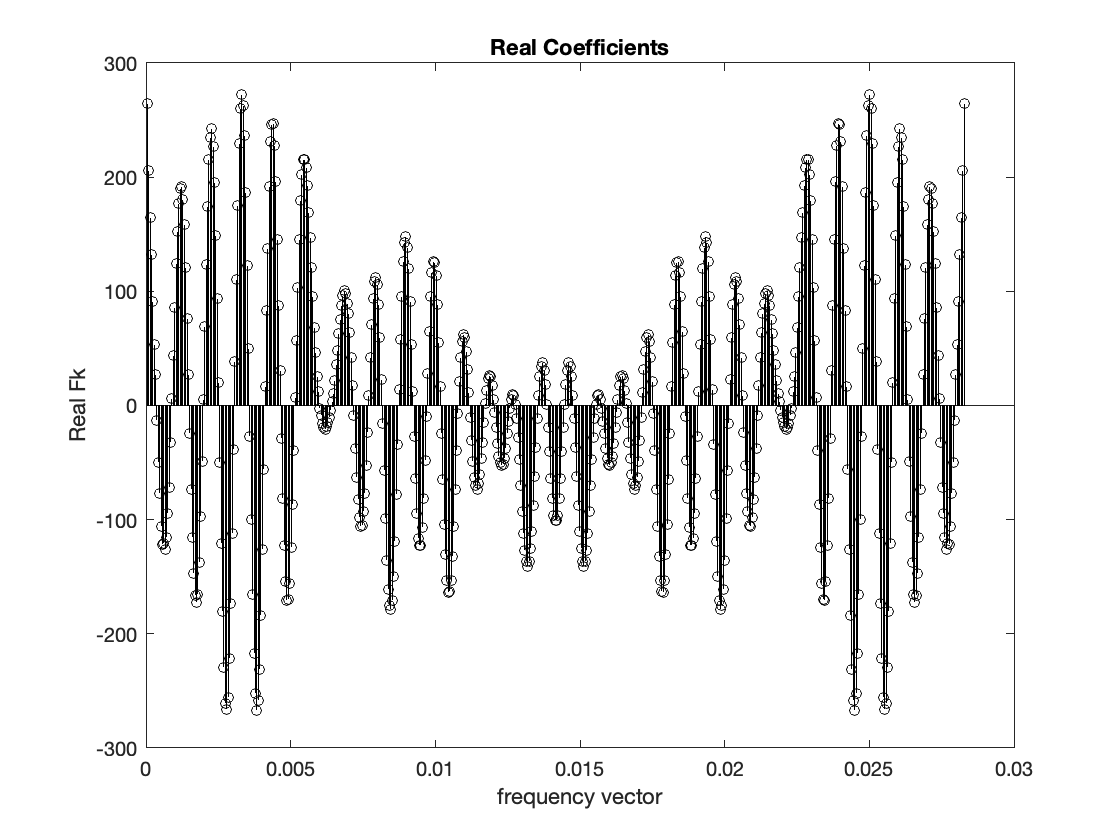

[Tnew,Mnew] = Interp_linear(HD28497(2:end,1),HD28497(2:end,2));
Tnew = Tnew*86400; %convert time from days to seconds
deltaT = Tnew(2)-Tnew(1);
Fs = 1/deltaT;           % Sampling frequency
T = deltaT;             % Sampling period
t = Tnew-Tnew(1);                % Time vector
L = numel(Tnew);         % Length of signal
X = Mnew ;              %signal with noise



%Fourier transformation    %Based on Ex 7-6 Gilat
F = fft(X)/L  ;            %fourier transform devided by number of data points
power = F.*conj(F)/L;
powernorm = power/max(power);   %normalized power spectrum
fk = (0:L-1)*(Fs/L);      %frequency vector Gilat 7-6
stem(fk(2:L),real(F(2:L)), 'ko','markersize',5)             %Threw out first number of F because seemingly significant outlier
xlabel('frequency vector')
ylabel('Real Fk')
title('Real Coefficients')

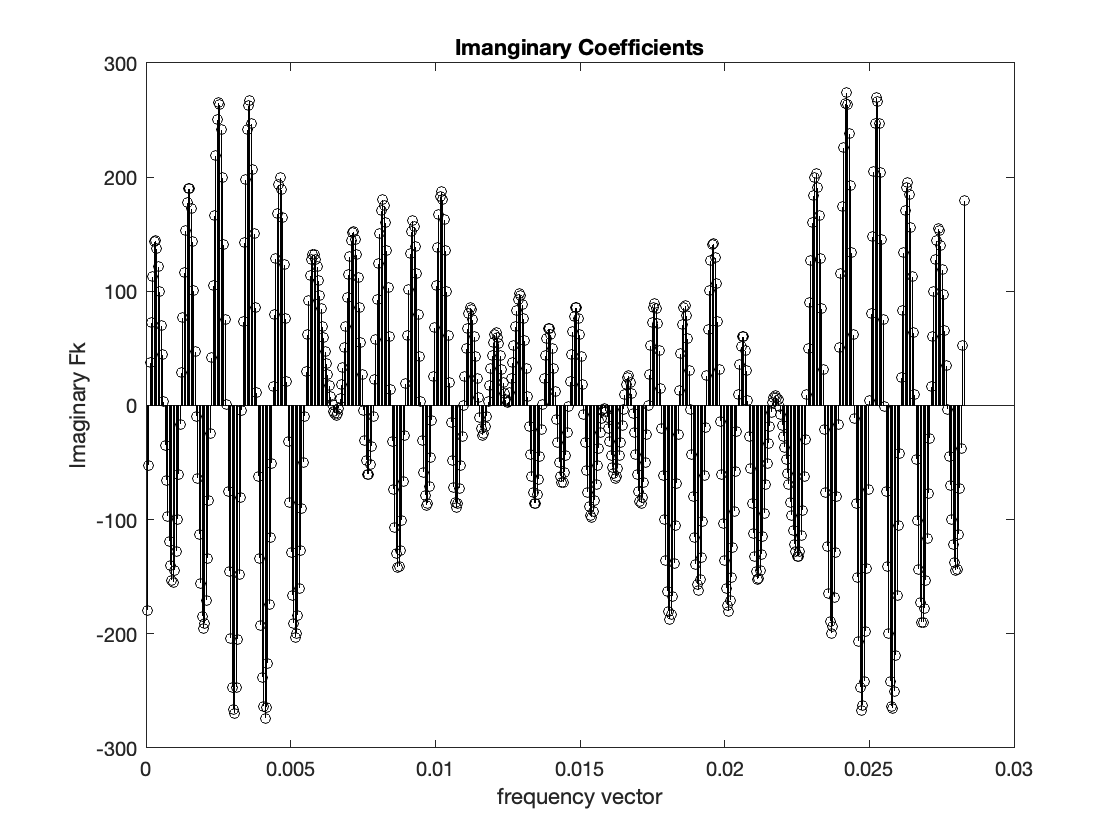

figure, stem(fk(2:L),imag(F(2:L)),'ko','markersize',5)
xlabel('frequency vector')
ylabel('Imaginary Fk')
title('Imanginary Coefficients')

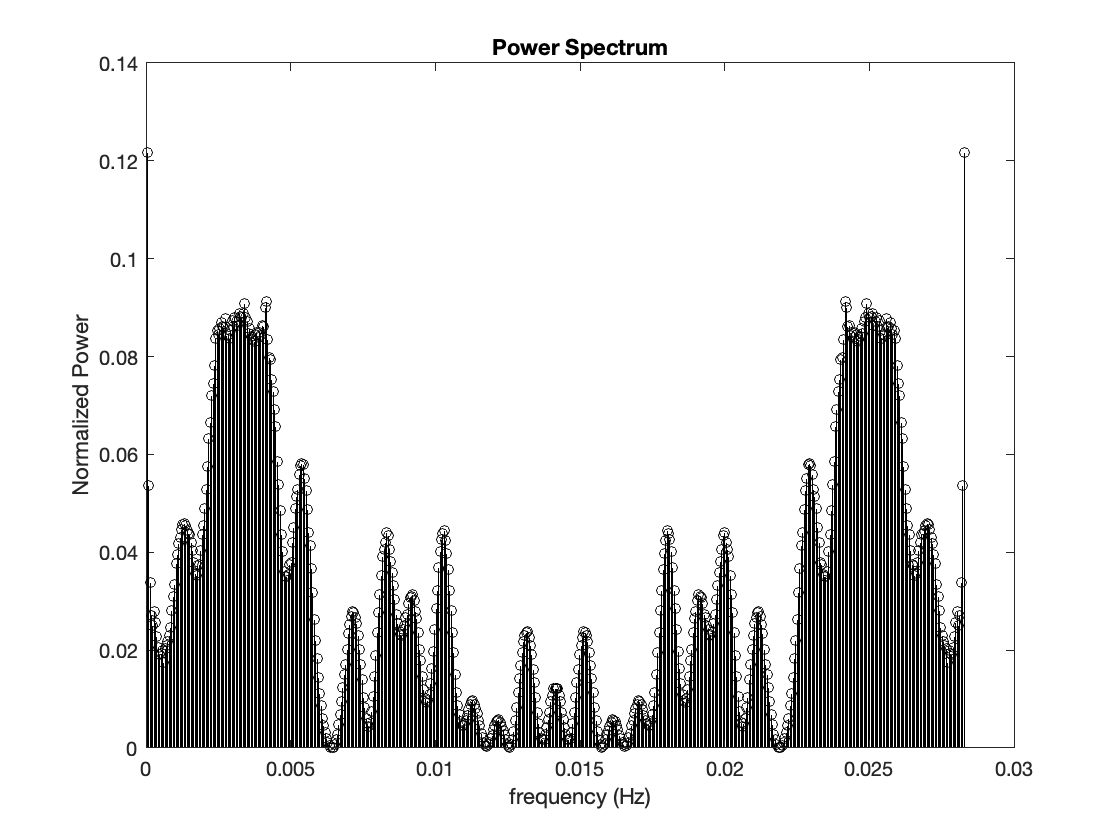

figure, stem(fk(2:L),powernorm(2:L),'ko','markersize',5)
xlabel('frequency (Hz)')
ylabel('Normalized Power')
title('Power Spectrum')

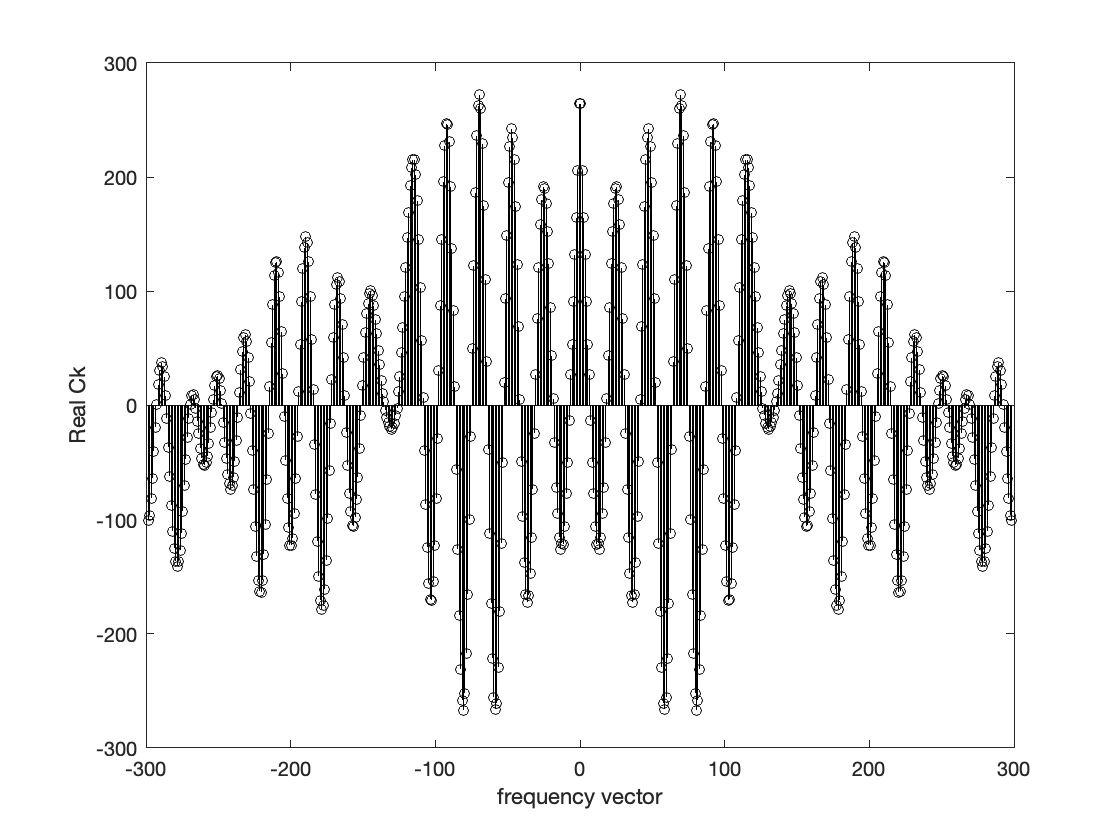


%Rearrange the spectrum using fftshift
C0 = fftshift(F(2:L));              %zero frequency in center (threw out first number of F as an outlier)
power0 = C0.*conj(C0)/L-1;
powernorm0 = power0/max(power0);   %normalized power spectrum
fk0 = (-L/2+1:L/2-1)*(Fs/L-1);      %frequency vector Gilat 7-6
stem(fk0,real(C0), 'ko','markersize',5)
xlabel('frequency vector')
ylabel('Real Ck')

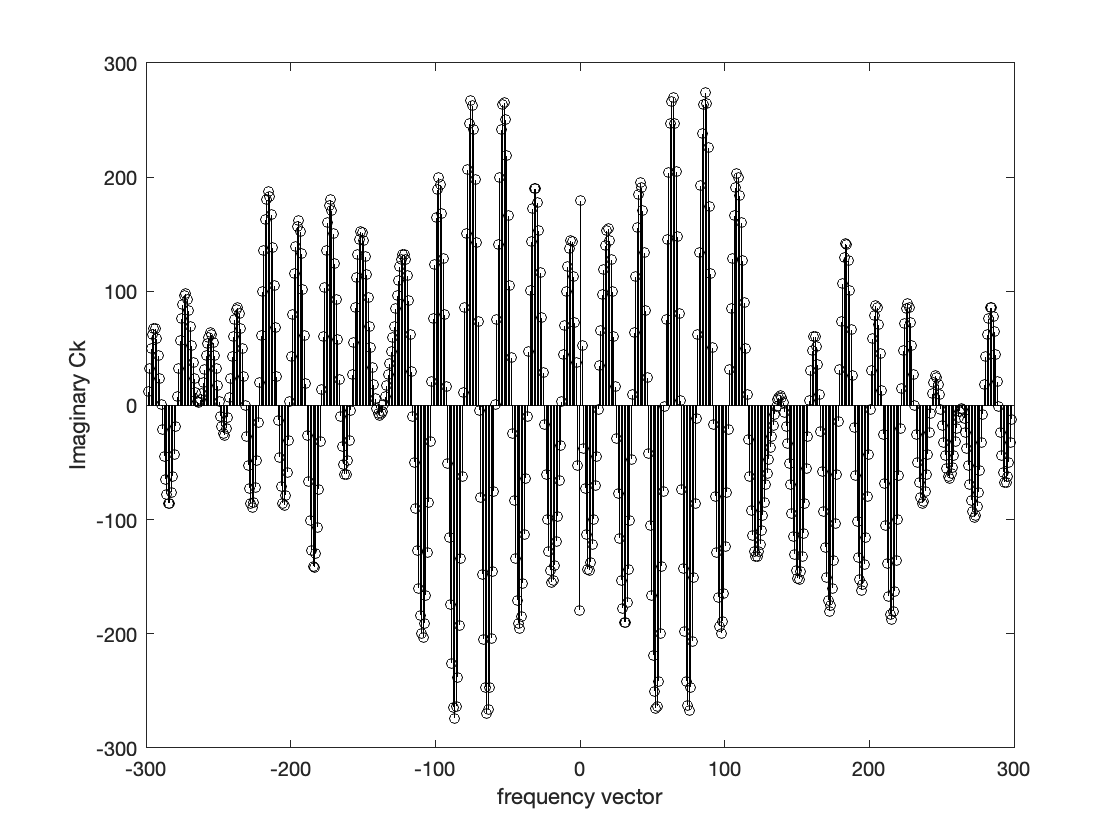

figure, stem(fk0,imag(C0),'ko','markersize',5)
xlabel('frequency vector')
ylabel('Imaginary Ck')

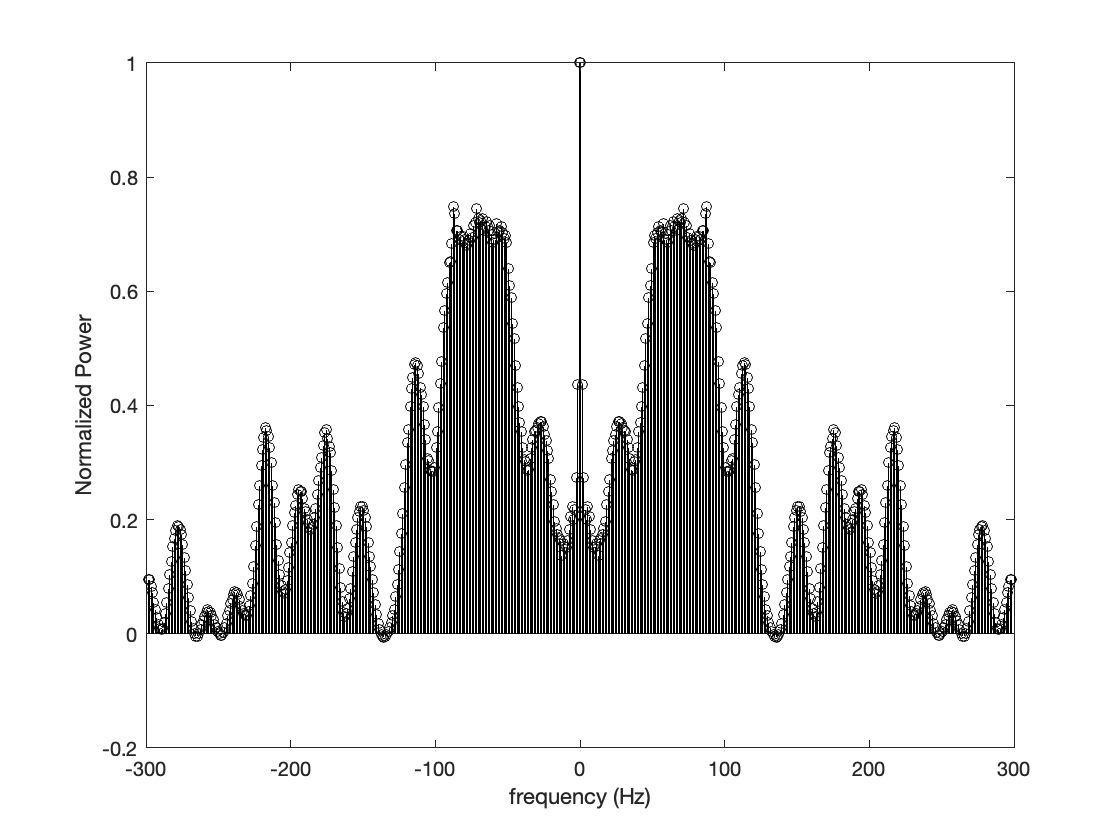

figure, stem(fk0,powernorm0,'ko','markersize',5)
xlabel('frequency (Hz)')
ylabel('Normalized Power')

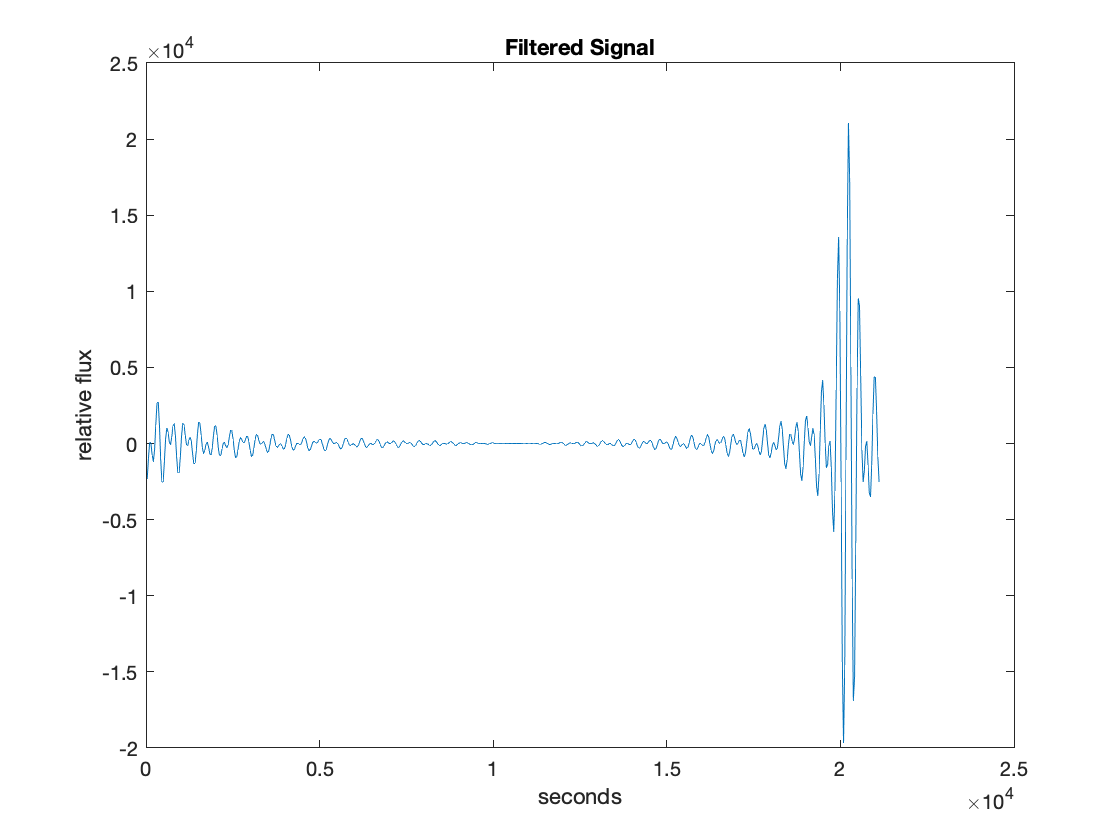

%Filtering out the noise            Based on Gilat Example 7-8

for k = 1:L-1
    if abs(fk0(k)) <= 50 | abs(fk0(k)) >= 90
        C0flter(k) = 0+0i;
    
    else
        C0flter(k) = C0(k);
    end
end


F0i = ifftshift(C0flter) * L-1;
finv = ifft(F0i);
figure, plot(t(2:L),real(finv))
title('Filtered Signal')
xlabel('seconds')
ylabel('relative flux')

## Milestone 4: Linear Combination of non-linear functions

###  BD55

Plot the raw data 

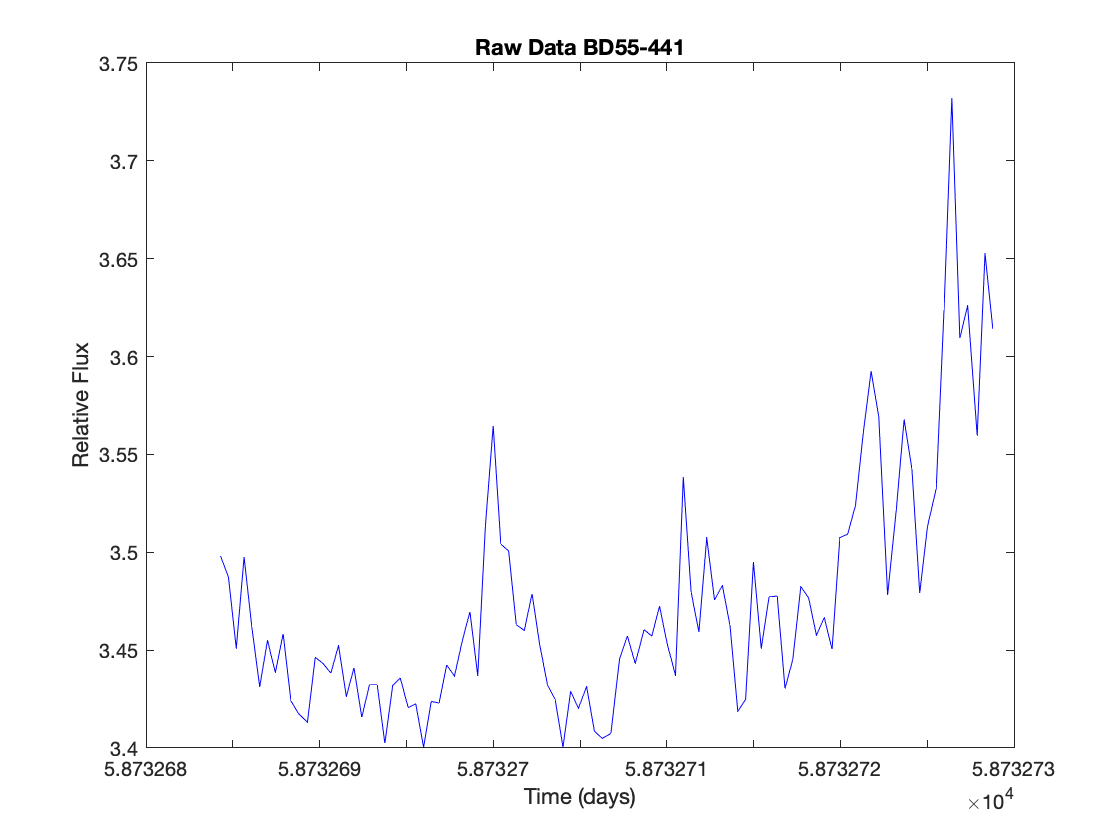

plot(BD55_441(1:100,1),BD55_441(1:100,2),'b');                  
title('Raw Data BD55-441');
xlabel('Time (days)');
ylabel('Relative Flux');

Use Linear Interpolation, then use a Fourier transform to attain the power spectrum

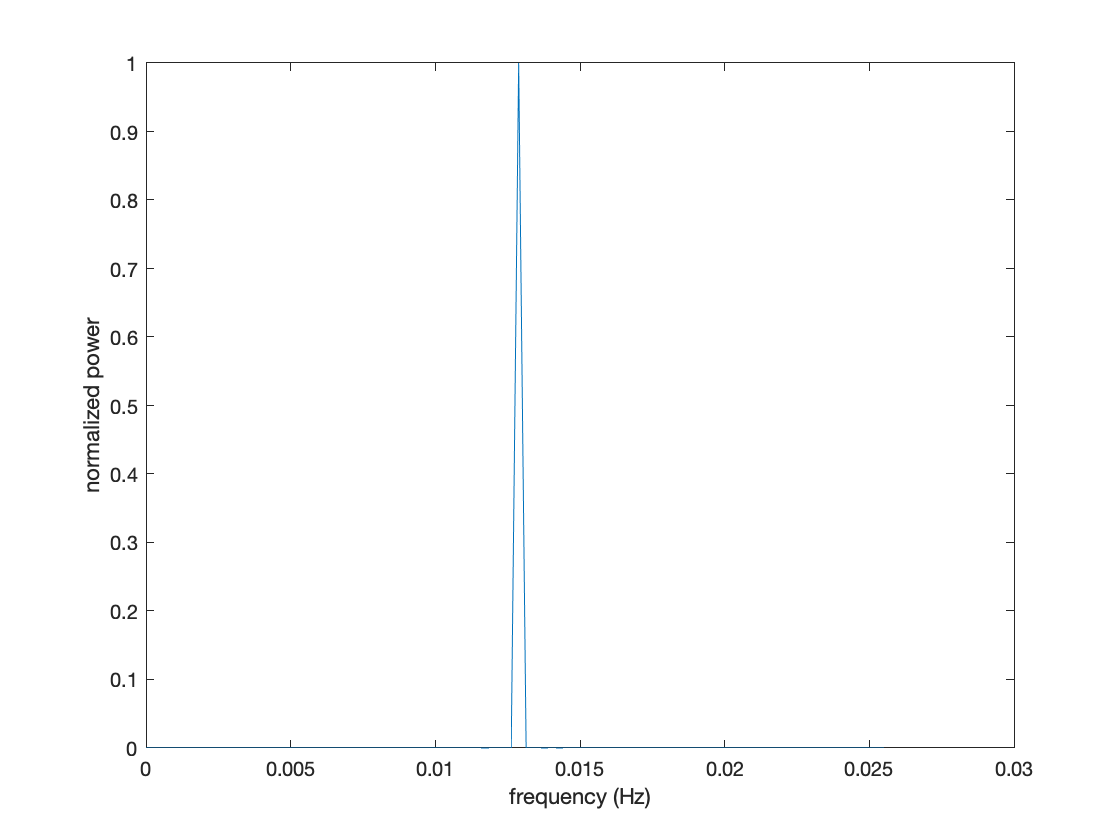

[Tnew,Mnew] = Interp_Lin(BD55_441(1:100,1),BD55_441(1:100,2));  
Tnews = Tnew*86400; %convert time from days to seconds
dt = Tnews(2) - Tnews(1);
[fk,powerNor] = EnergySpec(Tnews,Mnew,dt);

Functions for linear combination:

(main frequency is 0.0129 HZ, or 1,115 per Day.  Use this to choose my non-linear functions)

F1 =  @(x) x./x;
F2 =  @(x) cos(2*pi*(1115)).*(x);       
F3 =  @(x) sin(2*pi*(1115)).*(x);


%call the NLfit function

c = NLfit(F1,F2,F3,BD55_441(1:100,1),BD55_441(1:100,2))

c = 	1.0e+13 *

  -0.000000016070897
   0.000000000000894
   3.724622381729035


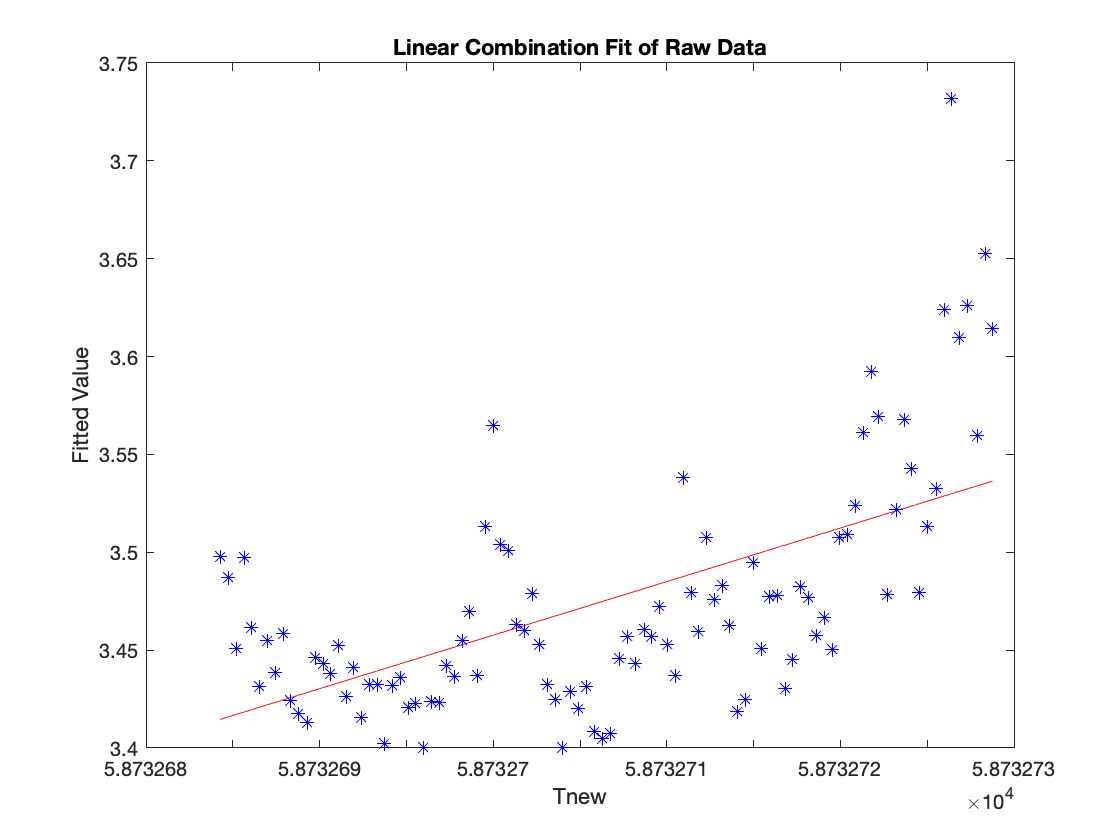




%plot

yfit =  c(1).*F1(Tnew) +  c(2).*F2(Tnew)  +  c(3).*F3(Tnew) ;
plot(Tnew,yfit,'r',BD55_441(1:100,1),BD55_441(1:100,2),'*b')
title('Linear Combination Fit of Raw Data')
xlabel('Tnew')
ylabel('Fitted Value')

### HD28497

Plot the raw data

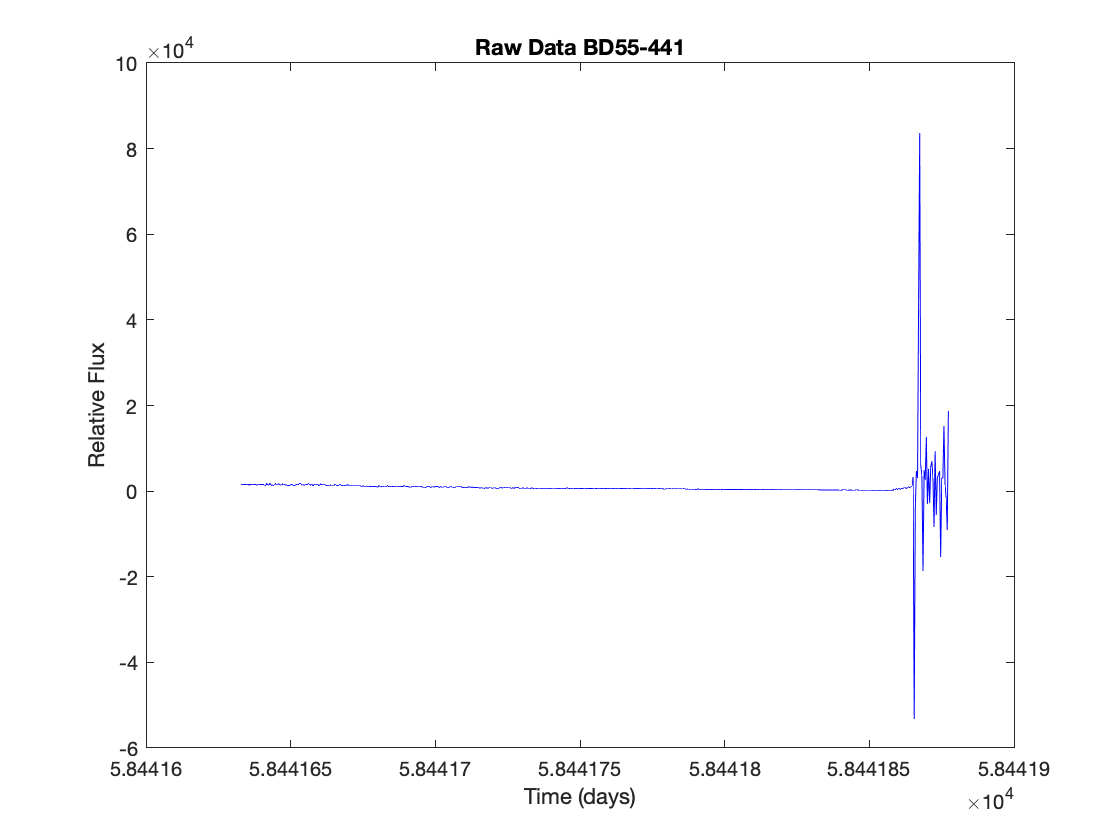

plot(HD28497(2:end,1),HD28497(2:end,2),'b');                  
title('Raw Data BD55-441');
xlabel('Time (days)');
ylabel('Relative Flux');

Use Linear Interpolation, then use a Fourier transform to attain the power spectrum

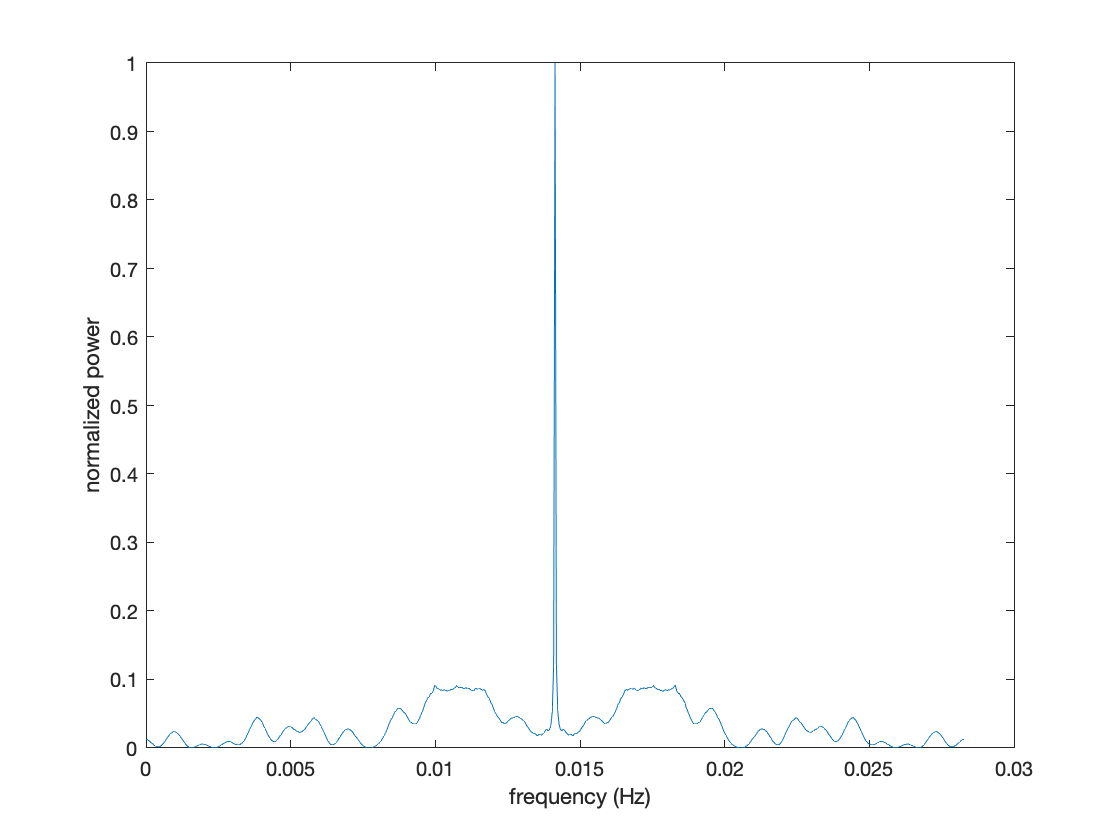

[Tnew,Mnew] = Interp_Lin(HD28497(2:end,1),HD28497(2:end,2));  
Tnews = Tnew*86400; %convert time from days to seconds
dt = Tnews(2) - Tnews(1);
[fk,powerNor] = EnergySpec(Tnews,Mnew,dt);

Functions for linear combination:

(main frequency at 0.0175 Hz or 1512 / day.  use this for non-linear functions)

F1 =  @(x) x./x;
F2 =  @(x) cos(2*pi*(1512)).*(x);       
F3 =  @(x) sin(2*pi*(1512)).*(x);


%call the NLfit function

c = NLfit(F1,F2,F3,HD28497(2:end,1),HD28497(2:end,2))

c = 	1.0e+14 *

   0.000000417432818
  -0.000000000006085
  -7.488964229280974


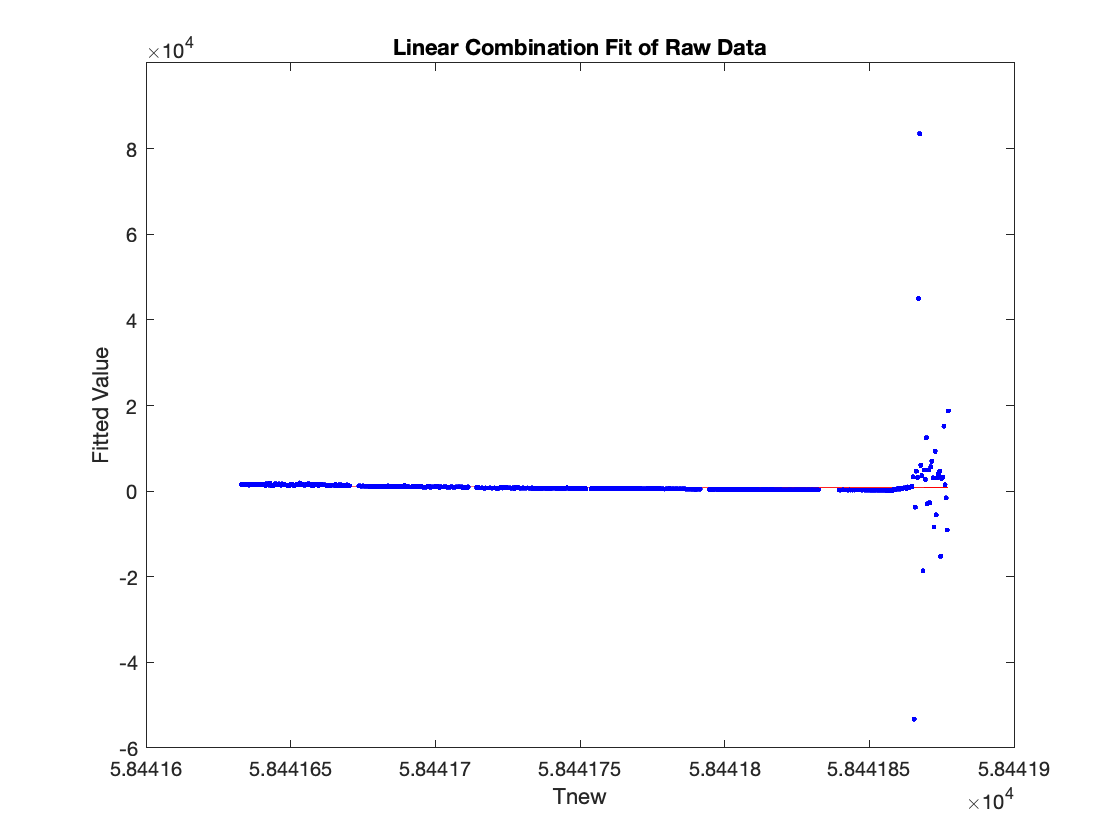




%plot

yfit =  c(1).*F1(Tnew) +  c(2).*F2(Tnew)  +  c(3).*F3(Tnew) ;
plot(Tnew,yfit,'r',HD28497(2:end,1),HD28497(2:end,2),'.b')
title('Linear Combination Fit of Raw Data')
xlabel('Tnew')
ylabel('Fitted Value')

%I think there is an erroneous power value showing up at about 0.014 Hz.
%Not sure why this artifact is appearing for more than one star?

##  Interpolation Functions

There are two different linear interpolation functions - the first is without built-in functions and the other is built-in. The results from both funcitons are similar.

Other interpolation methods are displayed.  

**Custom functions**

function [Tnew,Mnew] = Interp_Lin(T,M)
%This is Joe's custom linear interpolation:
%----

% --Sum all of the time differences between measurements--
n = numel(T);
sum = 0;
for l = 1:n-1
    sum = sum + abs(T(l+1) - T(l));
end

% --Find averaged time scale--
avg_dT = sum / (n-1);
Tnew = T(1):avg_dT:T(n);

% --Calculate Mnew values--
m = numel(Tnew);
Mnew = zeros(1,m);

Mnew(1) = M(1);
Mnew(m) = M(n);

for l = 2:m-1
    for k = 1:n
        if T(k) <= Tnew(l)
            if Tnew(l) <= T(k+1)
                Mnew(l) = (M(k+1) - M(k))./(T(k+1) - T(k)).*(Tnew(l)-T(k)) + M(k);
                %eq for a line. i.e. y = mx + b
            end
        end
    end
end

end

**Various built-in Matlab Functions**

function [Tnew,Mnew] = Interp_nearest(T,M)
%This uses the built-in function 'interp1' with method 'nearest'
%----

% --Sum all of the time differences between measurements--
n = numel(T);
sum = 0;
for l = 1:n-1
    sum = sum + abs(T(l+1) - T(l));
end

% --Find averaged time scale--
avg_dT = sum / (n-1);
Tnew = T(1):avg_dT:T(n);

% --Calculate Mnew values--
Mnew = interp1(T,M,Tnew,'nearest');
end

function [Tnew,Mnew] = Interp_linear(T,M)
%This uses the built-in function 'interp1' with method 'linear'
%----

% --Sum all of the time differences between measurements--
n = numel(T);
sum = 0;
for l = 1:n-1
    sum = sum + abs(T(l+1) - T(l));
end

% --Find averaged time scale--
avg_dT = sum / (n-1);
Tnew = T(1):avg_dT:T(n);

%--Calculate Mnew values--
Mnew = interp1(T,M,Tnew,'linear');
end

function [Tnew,Mnew] = Interp_spline(T,M)
%This uses the built-in function 'interp1' with method 'spline'
%----

% --Sum all of the time differences between measurements--
n = numel(T);
sum = 0;
for l = 1:n-1
    sum = sum + abs(T(l+1) - T(l));
end

% --Find averaged time scale--
avg_dT = sum / (n-1);
Tnew = T(1):avg_dT:T(n);

% --Calculate Mnew values--
Mnew = interp1(T,M,Tnew,'spline');
end

function [Tnew,Mnew] = Interp_polyfit(T,M)
%This uses the built-in function 'interp1' with method 'polyfit'
%----

% --Sum all of the time differences between measurements--
n = numel(T);
sum = 0;
for l = 1:n-1
    sum = sum + abs(T(l+1) - T(l));
end

% --Find averaged time scale--
avg_dT = sum / (n-1);
Tnew = T(1):avg_dT:T(n);

% --Calculate Mnew values--
n = numel(T);
p = polyfit(T,M,5);
Mnew = polyval(p,Tnew);
end


Joe's linear combo of non-linear functions function

function C = NLfit(F1,F2,F3,x,y) 
%documentation:  This program was developed from Gilat example 6-9

F1 = F1(x);
F2 = F2(x);
F3 = F3(x);

A(1,1) = sum(F1 .* F1);
A(1,2) = sum(F1 .* F2);
A(1,3) = sum(F1 .* F3);
A(2,2) = sum(F2 .* F2);
A(2,3) = sum(F2 .* F3);
A(3,3) = sum(F3 .* F3);

A(2,1) = A(1,2);    % A is symmetric
A(3,1) = A(1,3);
A(3,2) = A(2,3);

B(1,1) = sum(y .* F1);
B(2,1) = sum(y .* F2);
B(3,1) = sum(y .* F3);

%form is A*C=B, Therefore,

C = A\B;

end

Joe's power spectrum function

function [fk,powerNor] = EnergySpec(t,f,dt)
%this function is developed with refeernce to Gilat Program 7-4 and Example
%7-6

N = length(f);
F = fft(f)/N;
F0 = fftshift(F);

power = F0.*conj(F0)/N;

powerNor = power/max(power);

%Plot power Spectrum
fs = 1/dt;
fk = (0:N-1)*(fs/N);

plot(fk, powerNor)
xlabel('frequency (Hz)')
ylabel('normalized power')


end

